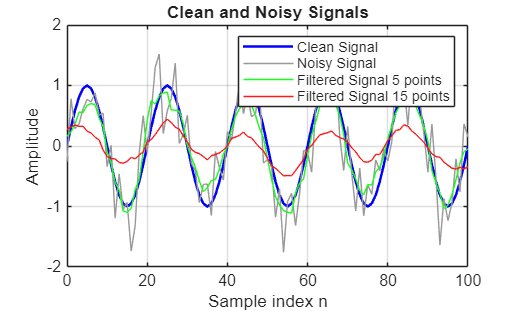

clear;
close all;
clc;

% Use the same random noise each time
rng(1);

%% Create a clean discrete-time signal

n = 0:100;
clean = sin(0.1*pi*n);

%% Add noise

noise = 0.4*randn(size(n));
measured = clean + noise;
scaled = 2 * measured;

%% Delaying signal 

delay = 5;

delayed = sin(0.1*pi*n+delay);

n_measured = 0:length(measured)-1;
n_delayed = 0:length(delayed)-1;

%% Five-Point Moving-Average Filter

h5 = ones(1,5)/5; % impulse response
filtered5 = conv(measured,h5,'same');

h15 = ones(1,15)/15;
filtered15 = conv(measured,h15,'same');

%% Display the clean and noisy signals

figure;

plot(n,clean,'b','LineWidth',1.5);
hold on;
plot(n,measured,'Color',[0.6 0.6 0.6]);

plot(n,filtered5,'Color',[0.1 0.99 0.1]);

plot(n,filtered15,'Color',[0.99 0.1 0.1]);

%plot(n,scaled,'Color',[0.9 0.9 0.6]);

%plot(n,delayed,'Color',[0.4 0.4 0.6]);

grid on;
xlabel('Sample index n');
ylabel('Amplitude');
title('Clean and Noisy Signals');
legend('Clean Signal','Noisy Signal','Filtered Signal 5 points', 'Filtered Signal 15 points');